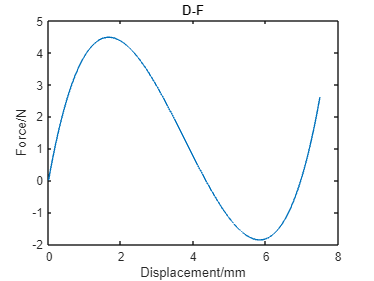

close all;
clear all;
l1=0.5/2;
L=11.5/2+l1;
r1=4.95/2;
H=7.5/2;
l3=1.5/2;
r2=4.68/2;
phi=deg2rad(52.4);
E=17E6;
%E2=2E9;
b=4/2;
h=0.76;
Iz=b*h^3/12;
des=1.29e-3;
lmd1=0.1;
lmd3=0.15;
%%K1
th0=solve_th0(L,lmd1,lmd3,H);
fct1=1.2;
fct2=1;
fct3=0.5;
k1=solve_k1(fct1,l1,L,lmd1,E,Iz);

k2=solve_k2(fct2,L,E,Iz,k1,lmd1,lmd3,H);

k3=fct3*solve_k3(k1,k2,E,b,h,th0,lmd1,lmd3,l1,l3,r1,r2,phi,H,L,Iz);
[m2,m3]=calculate_mass(lmd1,lmd3,L,des,th0,b,h);
v=1/3;%%(mm/s)
dt=0.01;%%(s);
t=0:dt:22.5;
g=9800;%%(mm/s^2)
d=v*t;
l2=L*(1-lmd1-lmd3)/cos(th0);
th0=-th0;
    F=lagarange_approach(d,H,v,th0,dt,k1,k2,k3,m2,m3,l2,g,L);
    plot(d,6*F);
title('D-F');
xlabel('Displacement/mm');
ylabel('Force/N');

save('lagrange_results_1.mat');